clear all;

% sine wave with and error
fs = 10000;
f1 = 10;
f2 = 100;
t = 0:1/fs:10/f1-1/fs;
%noise
e_range = 3.3/2^12*100; % +-7 LSB TUE
e_Uin = rand(1,length(t))*2*e_range-e_range;
% R1*sin(w1t+fi1) + R2*sin(w2t+fi2) + C
fi1 = rand(1)*pi/2

fi1 =    0.393452235757503


fi2 = rand(1)*pi/2

fi2 =    0.107768795319896


R1 = 1; 
R2 = 0.1;
C = 1.65;
x = R1*sin(2*pi*f1*t+fi1)+R2*sin(2*pi*f2*t+fi2)+C;
x_err = x + e_Uin;
plot(t,x,'b')
hold on;
plot(t,x_err,'r-')
hold off;

%least square method
n = length(x);
D = [cos(2*pi*f1*t)',sin(2*pi*f1*t)',cos(2*pi*f2*t)',sin(2*pi*f2*t)', ones(n,1)]; %trig identity to cos + sin for phase
DD = D'*D;
K = DD\D'*x_err' % least square

K =    0.383462132779244
   0.924791289609790
   0.010779433849055
   0.100318562417384
   1.650527852908985


R1_est = sign(K(1))*sqrt(K(1)^2+K(2)^2)

R1_est =    1.001140418030231


R2_est = sign(K(3))*sqrt(K(3)^2+K(4)^2)

R2_est =    0.100896036391906


fi1_est = atan(-K(2)/K(1))+pi/2 

fi1_est =    0.393069170689681


fi2_est = atan(-K(4)/K(3))+pi/2 

fi2_est =    0.107041333197837


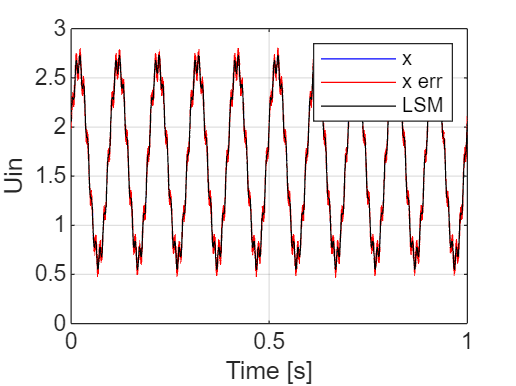


%plotting
x_est = R1_est*sin(2*pi*f1*t+fi1_est)+R2_est*sin(2*pi*f2*t+fi2_est)+K(5);
hold on;
plot(t,x_est,'k');
hold off;
grid on;
xlabel('Time [s]');
ylabel('Uin');
legend('x','x err','LSM')

title('Multisine LSM')

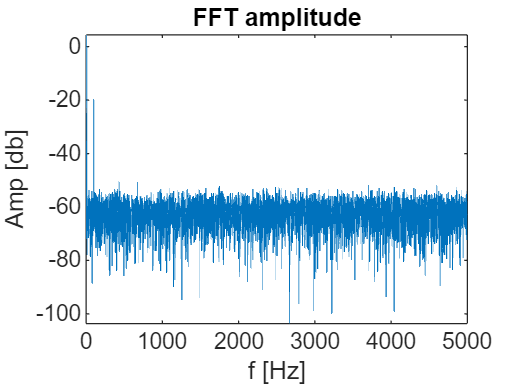

% Calculating components with FFT
f = [0:length(t)-1]*fs/length(t);
f_egy = f(1:end/2);
X_err = fft(x_err);
X_err_egyodlalas = abs(X_err)/length(x);
X_err_egyodlalas = [X_err_egyodlalas(1),2*X_err_egyodlalas(2:end/2)];
X_err_f = angle(X_err(1:end/2));

% Plotting
plot(f_egy,20*log10(X_err_egyodlalas))
xlabel('f [Hz]')
ylabel('Amp [db]')
title('FFT amplitude')

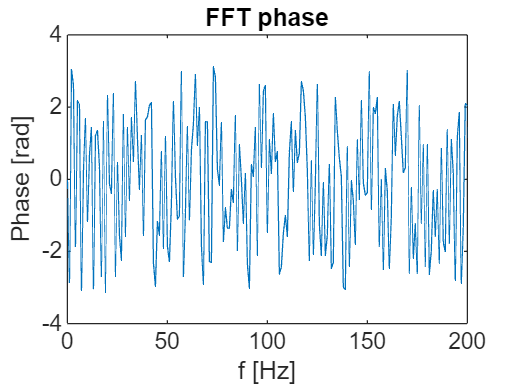

plot(f_egy,X_err_f)
xlabel('f [Hz]')
ylabel('Phase [rad]')
title('FFT phase')
xlim([0,200])


% Results comparison
R1_est = sign(K(1))*sqrt(K(1)^2+K(2)^2)

R1_est =    1.001140418030231


R2_est = sign(K(3))*sqrt(K(3)^2+K(4)^2)

R2_est =    0.100896036391906


fi1_est = atan(-K(2)/K(1))+pi/2 

fi1_est =    0.393069170689681


fi2_est = atan(-K(4)/K(3))+pi/2 

fi2_est =    0.107041333197837


R1_fft = X_err_egyodlalas(f_egy==10)

R1_fft =    1.001140418030232


R2_fft = X_err_egyodlalas(f_egy==100)

R2_fft =    0.100896036391906


f1_fft = X_err_f(f_egy==10)+pi/2

f1_fft =    0.393069170689680


f2_fft = X_err_f(f_egy==100)+pi/2

f2_fft =    0.107041333197841
